## Setup

clear; clc; close all;

if(~isdeployed)
  cd(fileparts(matlab.desktop.editor.getActiveFilename));
end

addpath("C:\Users\trent\UofT\Research\Leukemia\Code")

p.BSA = 0.82;
p.F = 0.22;
p.k_a = 31.2;
p.k_20 = 12.72;
p.FM_3 = 0.019;
p.k_me = 9.9216;
p.CL_6tgn = 0.219*p.BSA^1.16;
p.k_ma = 2.3765;

p.Base = 2.34;
p.k_tr = 0.148;
p.slope = 0.242;
% p.gamma = 0.769;
% p.gamma = 0.849;
p.gamma = 0.9;
% p.gamma = 0.5;

x_target = 1.5; % Neutrophil concentration, units of G/L
ubar = p.k_20*p.CL_6tgn/(p.slope*p.FM_3*p.k_me*p.F)*(1 - (x_target/p.Base)^p.gamma)

ubar = 72.7221

nominalDose = 50*p.BSA;

xbar_4 = (1-p.slope*p.FM_3*p.k_me*p.F*ubar/(p.CL_6tgn*p.k_20))^(1/p.gamma)*(p.Base*p.k_ma/p.k_tr);
xbar = [p.F*ubar/p.k_a; p.F*ubar/p.k_20; p.FM_3*p.k_me*p.F*ubar/(p.CL_6tgn*p.k_20); xbar_4; xbar_4; xbar_4; xbar_4; (1-p.slope*p.FM_3*p.k_me*p.F*ubar/(p.CL_6tgn*p.k_20))^(1/p.gamma)*p.Base];

Trajectory of the nonlinear system starting from initial condition specified in paper and using ubar as input:

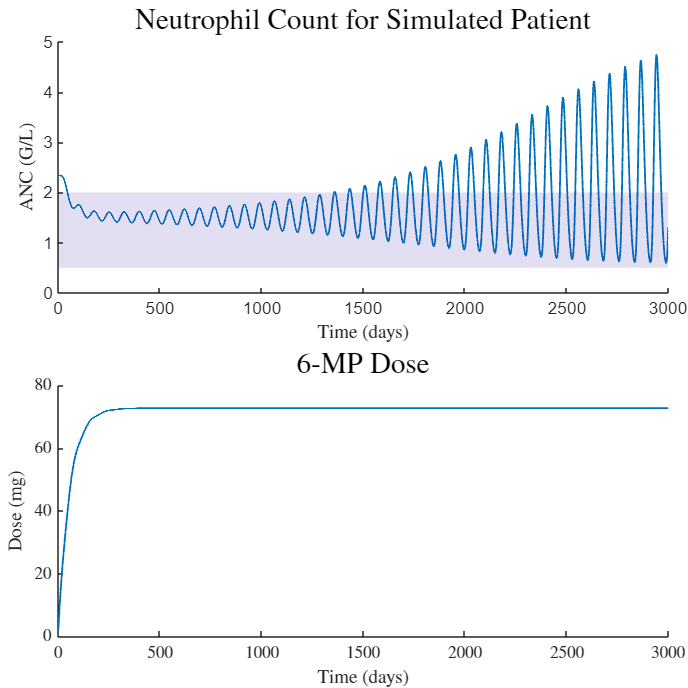

x0 = [0; 0; 0; (p.Base*p.k_ma)/p.k_tr; (p.Base*p.k_ma)/p.k_tr; (p.Base*p.k_ma)/p.k_tr; (p.Base*p.k_ma)/p.k_tr; p.Base];

% u = @(t) ubar * 21/14 .* (mod(t,21) < 14);
% u = @(t) nominalDose * 21/14 .* (mod(t,21) < 14);
% u = @(t) nominalDose * 21/14 + 0.*t;
% u = @(t) 0*t;
% u = @(t) 10 .* (t < 5);
u = @(t) ubar*(1-exp(-t/55)) + 2*cos(t*2*pi/80).*exp(-t/75);

[t,x] = ode45(@(t,x) JostModelWithParams(t,x,u(t),p), 0:0.5:3000, x0);

x4_increasing = x(:,8) < p.Base*(1-p.slope*x(:,3)).^(1/p.gamma);

f = figure('Position',[0 0 500 500]);
tiledlayout(2,1,"TileSpacing","tight","Padding","tight");

nexttile;
hold on
plot(t,x(:,8),'linewidth',1)
% yline(x_target,'k--')
area([0 t(end)], [2 2], 0.5,"FaceColor","flat","ShowBaseLine","off","FaceAlpha",0.15,"Linestyle","None");
title("Neutrophil Count for Simulated Patient",'Interpreter','latex','FontSize',16)
xlabel('Time (days)','Interpreter','latex')
ylabel("ANC (G/L)",'Interpreter','latex')

nexttile;
hold on
plot(t,u(t),'linewidth',1)
title("6-MP Dose",'Interpreter','latex','FontSize',16)
xlabel('Time (days)','Interpreter','latex')
ylabel("Dose (mg)",'Interpreter','latex')

set(gca,'TickLabelInterpreter','latex')

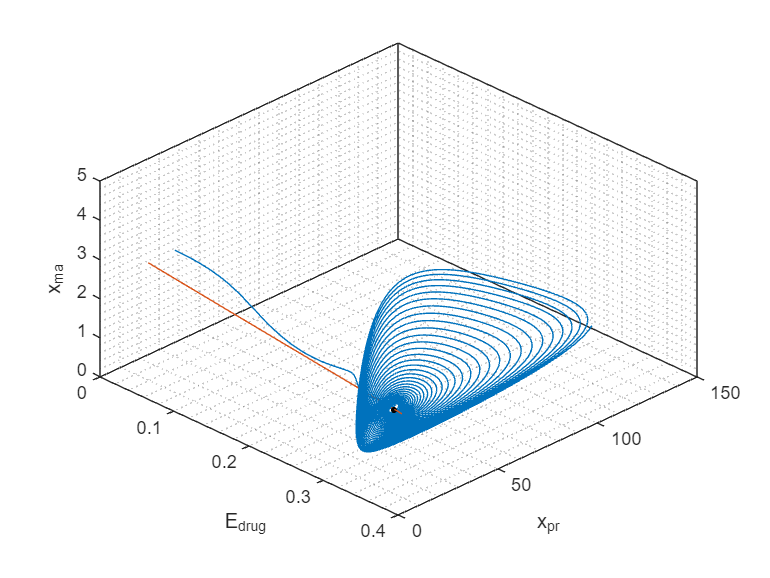

% exportgraphics(f,'EquilibriumDose.png','Resolution',300)


figure;
hold on
plot3(p.slope*x(:,3),x(:,4),x(:,8));

E_vals = p.slope*min(x(:,3)):0.01:p.slope*max(x(:,3))+0.02;
plot3(E_vals,repmat(xbar(4),size(E_vals)),p.Base*(1-E_vals).^(1/p.gamma))
plot3(p.slope*xbar(3),xbar(4),xbar(8),'k.','MarkerSize',10)

points(1,:) = [E_vals(1) x(1,4) x(1,8)];
points(2,:) = [E_vals(1) 0 x(1,8)];
points(3,:) = [E_vals(end) 0 p.Base*(1-E_vals(end))^(1/p.gamma)];
points(4,:) = [E_vals(end) x(1,4) p.Base*(1-E_vals(end))^(1/p.gamma)];
% fill3(points(:,1),points(:,2),points(:,3),'r','FaceAlpha',0.3)

xlabel('E_{drug}')
ylabel('x_{pr}')
zlabel('x_{ma}')
box on
grid minor
view([45 45])



% plot(t_nl_40mg,x4_increasing)

% set(f,'Visible','on')
% exportgraphics(f,'EquilibriumDose.png','Resolution',300)

screenSize = get(0,'screensize');

% allStatesFig = figure('Position',[screenSize(3)/2 50 1000 1000]);
% fig3 = tiledlayout(8,1);
% title(fig3,'State Trajectories')
% 
% for i = 1:size(x,2)
%     ax(i) = nexttile;
%     hold on
%     plot(t,x(:,i))
%     ylabel("x_"+i)
%     ylim('padded')
%     box on
%     grid on
% end
% xlabel('Time (days)')
% linkaxes(ax,'x')
% xlim([0 400])
% set(allStatesFig,'CurrentAxes',ax(3))
% plot(t,x4_increasing)